## Giraffe

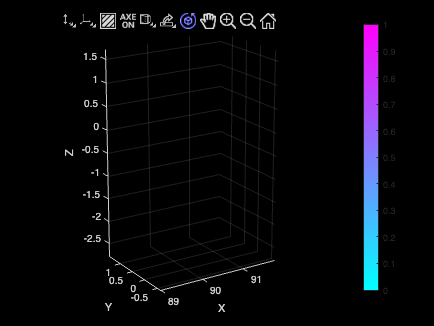

pcdFilePath = "/Users/ikuta/Documents/Projects/wildpose-self-calibrator/data/giraffe_walk/accumulation.pcd";

% load a pcd file
ptCloud = pcread(pcdFilePath);

xlims = [89 91.8];
ylims = [-0.6 1.45];
zlims = [-2.8 1.7];

% % display
% figure
% % Target Reflectivity: expressed from 0 to 255. Among them, 0 to 150 correspond to diffuse scattering objects with reflectivity between 0 and 100%; and 151 to 255 correspond to total reflection objects.
% pcshow( ...
%     ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity), ...
%     "AxesVisibility","on")
% xlabel("X")
% ylabel("Y")
% zlabel("Z")
% colorbar
% colormap("cool")
% xlim(xlims)
% ylim(ylims)
% zlim(zlims)

locations = ptCloud.Location;
x_cond = (locations(:, 1) >= xlims(1)) & (locations(:, 1) <= xlims(2));
y_cond = (locations(:, 2) >= ylims(1)) & (locations(:, 2) <= ylims(2));
z_cond = (locations(:, 3) >= zlims(1)) & (locations(:, 3) <= zlims(2));

total_points_within_limits = sum(x_cond & y_cond & z_cond)

total_points_within_limits = 11059

## Martial eagle

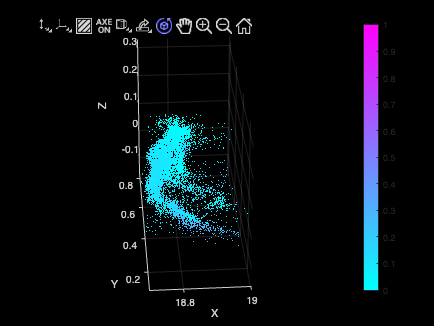

pcdFilePath = "/Users/ikuta/Documents/Projects/wildpose-self-calibrator/data/martial_eagle/accumulation.pcd";

% load a pcd file
ptCloud = pcread(pcdFilePath);

xlims = [18.7 19];
ylims = [0.1 0.84];
zlims = [-0.16 0.33];

% display
figure
% Target Reflectivity: expressed from 0 to 255. Among them, 0 to 150 correspond to diffuse scattering objects with reflectivity between 0 and 100%; and 151 to 255 correspond to total reflection objects.
pcshow( ...
    ptCloud.Location, ptCloud.Intensity / max(ptCloud.Intensity), ...
    "AxesVisibility","on")
xlabel("X")
ylabel("Y")
zlabel("Z")
colorbar
colormap("cool")
xlim(xlims)
ylim(ylims)
zlim(zlims)

locations = ptCloud.Location;
x_cond = (locations(:, 1) >= xlims(1)) & (locations(:, 1) <= xlims(2));
y_cond = (locations(:, 2) >= ylims(1)) & (locations(:, 2) <= ylims(2));
z_cond = (locations(:, 3) >= zlims(1)) & (locations(:, 3) <= zlims(2));

total_points_within_limits = sum(x_cond & y_cond & z_cond)

total_points_within_limits = 8417